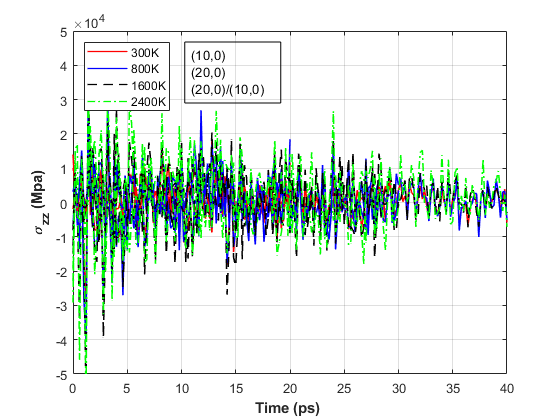

clc
clear all;
close all


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K
C1_300K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.1.Equi.txt','rt');
C1_800K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.1.Equi.txt','rt');
C1_1600K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.1.Equi.txt','rt');
C1_2400K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.1.Equi.txt','rt');

 C1a_300K= cell2mat(textscan(C1_300K,'%f%f%f%f%f','headerlines',1));
 C1a_800K= cell2mat(textscan(C1_800K,'%f%f%f%f%f','headerlines',1));
 C1a_1600K= cell2mat(textscan(C1_1600K,'%f%f%f%f%f','headerlines',1));
 C1a_2400K= cell2mat(textscan(C1_2400K,'%f%f%f%f%f','headerlines',1));



%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.
C2_300K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.1.Equi.txt','r');
C2_800K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.1.Equi.txt','r');
C2_1600K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1600K.1.Equi.txt','r');
C2_2400K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.1.Equi.txt','r');

C2b_300K= cell2mat(textscan(C2_300K,'%f%f%f%f%f','headerlines',1));
C2b_800K = cell2mat(textscan(C2_800K,'%f%f%f%f%f','headerlines',1));
C2b_1600K = cell2mat(textscan(C2_1600K,'%f%f%f%f%f','headerlines',1));
C2b_2400K = cell2mat(textscan(C2_2400K,'%f%f%f%f%f','headerlines',1));


%%% MWCNT.300K.
M_300K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.1.Equi.txt','r');
M_800K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.1.Equi.txt','r');
M_1600K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.1.Equi.txt','r');
M_2400K =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.1.Equi.txt','r');

 M1_300K= cell2mat(textscan(M_300K,'%f%f%f%f%f','headerlines',1));
 M1_800K= cell2mat(textscan(M_800K,'%f%f%f%f%f','headerlines',1));
 M1_1600K= cell2mat(textscan(M_1600K,'%f%f%f%f%f','headerlines',1));
 M1_2400K= cell2mat(textscan(M_2400K,'%f%f%f%f%f','headerlines',1));


fclose(M_300K);
fclose(M_800K);
fclose(M_1600K);
fclose(M_2400K);

fclose(C2_300K);
fclose(C2_800K);
fclose(C2_1600K);
fclose(C2_2400K);

fclose(C1_300K);
fclose(C1_800K);
fclose(C1_1600K);
fclose(C1_2400K);

figure(1)  %%% equilibtration...E total vs time
plot(C1a_300K(:,1),C1a_300K(:,5),'r',"LineWidth",1); hold on
plot(C1a_800K(:,1),C1a_800K(:,5),'b',"LineWidth",1); hold on
plot(C1a_1600K(:,1),C1a_1600K(:,5),'--k',"LineWidth",1); hold on
plot(C1a_2400K(:,1),C1a_2400K(:,5),'-.g',"LineWidth",1); hold on
plot(C2b_300K(:,1),C2b_300K(:,5),'r',"LineWidth",1); hold on
plot(C2b_800K(:,1),C2b_800K(:,5),'b',"LineWidth",1); hold on
plot(C2b_1600K(:,1),C2b_1600K(:,5),'--k',"LineWidth",1); hold on
plot(C2b_2400K(:,1),C2b_2400K(:,5),'-.g',"LineWidth",1);  hold on
plot(M1_300K(:,1),M1_300K(:,5),'r',"LineWidth",1); hold on
plot(M1_800K(:,1),M1_800K(:,5),'b',"LineWidth",1); hold on
plot(M1_1600K(:,1),M1_1600K(:,5),'--k',"LineWidth",1); hold on
plot(M1_2400K(:,1),M1_2400K(:,5),'-.g',"LineWidth",1); 


xlabel('Time (ps) ',"FontWeight","bold")
ylabel('\sigma_{zz} (Mpa)',"FontWeight","bold")
legend('300K','800K','1600K','2400K','','','','','','','','','Location','northwest')
xlim([0 40])
 ylim([-50000 50000])
grid on
annotation('textbox', [0.33, 0.7, 0.1, 0.2], 'String', {'(10,0)','(20,0)','(20,0)/(10,0)'},'FitBoxToText',"on")
% annotation('textbox', [0.4, 0.45, 0.1, 0.1], 'String', "(20,0),60A",'FitBoxToText',"on")
% annotation('textbox', [0.4, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),60A",'FitBoxToText',"on")

saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_Equi.jpg')

hold off